# Getting Started: Tool Validation Kit CLI

## Select test and report folder

cp = currentProject;
testFolder = fullfile(cp.RootFolder, "UnitTestFolder");

% Unzip zipped unit test folder
if ~isfolder(testFolder)
    unzipFiles(fullfile(tvkAppRoot, "UnitTestFolder.zip"))
end

reportFolder = fullfile(cp.RootFolder, "results");

## Create tvk object and enable custom report generation

Create the tvk base instance and set custom report gen flag to true.

obj = tvk.TVKBase(testFolder, reportFolder);

obj.EnableCustomReportGen = 1;

## Examine high level and detailed test tables

obj.TestTable

ans = 33×3 table
                 TestList                        ParentList           Selected
    ___________________________________    _______________________    ________

    "ArithmeticTest"                       "Base"                      true   
    "ComputationalGeometryTests"           "Base"                      true   
    "ContainersTest"                       "Base"                      true   
    "ControlFlowTest"                      "Base"                      true   
    "DatastoreTest"                        "Base"                      true   
    "DatetimeTest"                         "Base"                      true   
    "FileIOTest"                           "Base"                      true   
    "GraphicsImageTests"                   "Base"                      true   
    "LinearAlgebraTest"                    "Base"                      true   
    "Matric


obj.DetailedTestTable

ans = 328×3 table
            Test                     TestClass              TestFolder
    ____________________    ____________________________    __________

    "additionTest"          "ArithmeticTest"                  "Base"  
    "subtractionTest"       "ArithmeticTest"                  "Base"  
    "multiplicationTest"    "ArithmeticTest"                  "Base"  
    "rightDivisionTest"     "ArithmeticTest"                  "Base"  
    "roundTest"             "ArithmeticTest"                  "Base"  
    "hexConversionTest"     "ArithmeticTest"                  "Base"  
    "testTriangulation"     "ComputationalGeometryTests"      "Base"  
    "testSTLWrite"          "ComputationalGeometryTests"      "Base"  
    "ClassTest"             "ContainersTest"                  "Base"  
    "StructTest"            "ContainersTest"                  "Base"  
    "CellArrayTest"        

## Select tests to run

selectedTests = [
%     "ImageProcessingTest"
%     "SignalToolboxTests"
%     "StatisticsMachineLearningTests"
    "FileIOTest"
    ];

obj.selectTests(selectedTests);

## Run selected tests

obj.runTests();

Performing dependency analysis to determine all the Toolboxes being tested...  
     Name     Version    ProductNumber
    ______    _______    _____________

    MATLAB     23.2            1      

... Dependency analysis complete.

Run selected test suite... 
 Running FileIOTest
Running FileIOTest
  Setting up FileIOTest
    Evaluating TestClassSetup: openFiles
  Done setting up FileIOTest in 0.0011407 seconds
   Running FileIOTest/filepartsPoint
### Running test: FileIOTest/filepartsPoint
    Evaluating Test: filepartsPoint
.   Done FileIOTest/filepartsPoint in 0.1223 seconds
   Running FileIOTest/directoryPoint
### Running test: FileIOTest/directoryPoint
    Evaluating Test: directoryPoint
.   Done FileIOTest/directoryPoint in 0.19226 seconds
   Running FileIOTest/fileOpenPoint
### Running test: FileIOTest/fileOpenPoint
    Evaluating Test: fileOpenPoint
.   Done FileIOTest/fileOpe

## Generate custom report

obj.generateReport();

Generating Custom Report... 
... Report Generation Complete
Report saved to: C:\projects\TVKMain\toolvalidationkit\results\MATLAB_Tool_Validation_Report_20240304T104301.docx


## Create new tests

filename = "AmazingTests.m";

createNewTest(filename);

## Run TVK App UI

Alternatively to running the tests and generating reports using the TVK CLI, you can perform the same operations using the UI.

Please follow the instructions in "Tool Validation Kit App Guide.pdf" to get started. You can find this document in the "Help" section of the app toolbar.

You can also launch the app in the Apps gallery of the MATLAB toolstrip once the Tool Validation Kit.mltbx toolbox file is installed.

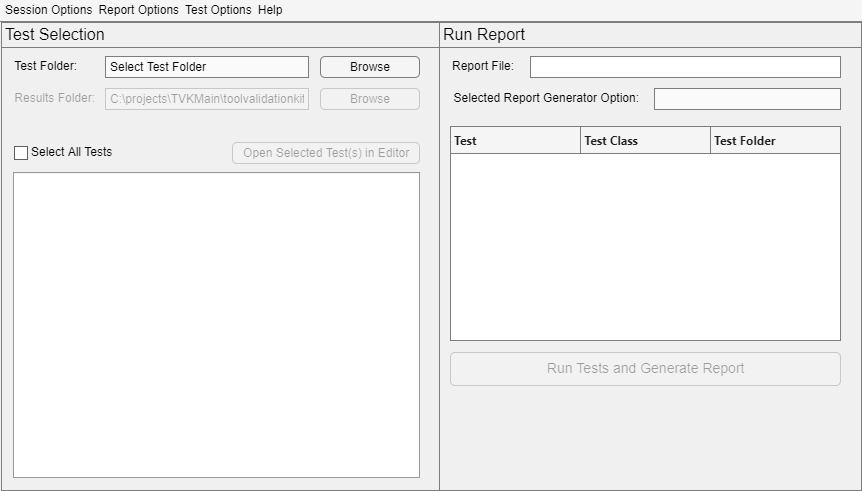


ans =

     []



runToolValidationKitApp()